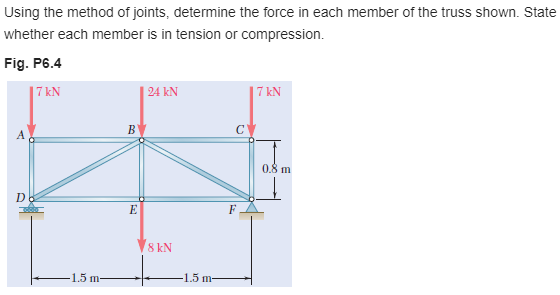

[https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-4P-solution-9780077687304](https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-4P-solution-9780077687304) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

E = sym('E');
A = sym('A');
theta = atand(sym(0.8)/sym(1.5))*u.deg;

# truss

t = Truss;
t = t.add('reaction', {0 'Rdy'}, [0 0]);
t = t.add('reaction', {'Rfx' 'Rfy'}, [3 0]*u.m);
t = t.add('concentrated', [0 -7]*u.kN, [0 0.8]*u.m);
t = t.add('concentrated', [0 -24]*u.kN, [1.5 0.8]*u.m);
t = t.add('concentrated', [0 -8]*u.kN, [1.5 0]*u.m);
t = t.add('concentrated', [0 -7]*u.kN, [3 0.8]*u.m);
t = t.add('joint', 'A', [0 0.8]*u.m);
t = t.add('joint', 'B', [1.5 0.8]*u.m);
t = t.add('joint', 'C', [3 0.8]*u.m);
t = t.add('joint', 'D', [0 0]);
t = t.add('joint', 'E', [1.5 0]*u.m);
t = t.add('joint', 'F', [3 0]*u.m);
t = t.add('member', 'Fab', [0 0.8]*u.m, [1.5 0.8]*u.m);
t = t.add('member', 'Fbc', [1.5 0.8]*u.m, [3 0.8]*u.m);
t = t.add('member', 'Fcf', [3 0.8]*u.m, [3 0]*u.m);
t = t.add('member', 'Fef', [1.5 0]*u.m, [3 0]*u.m);
t = t.add('member', 'Fde', [0 0], [1.5 0]*u.m);
t = t.add('member', 'Fad', [0 0.8]*u.m, [0 0]);
t = t.add('member', 'Fbd', [1.5 0.8]*u.m, [0 0]);
t = t.add('member', 'Fbe', [1.5 0.8]*u.m, [1.5 0]*u.m);
t = t.add('member', 'Fbf', [1.5 0.8]*u.m, [3 0]*u.m);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & -\frac{45.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{1} & -\frac{5.6}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{2} & -\frac{45.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{2} & -\frac{207.2}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{3} & -\frac{45.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{3} & -\frac{5.6}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{4} & -\frac{90.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{4} & 0\\ u_{5} & -\frac{45.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{5} & -\frac{213.6}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{6} & 0\\ v_{6} & 0 \end{array}\right)$$

fa

$$fa = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fad} & -7\,\mathrm{kN}\\ \mathrm{Fbc} & 0\\ \mathrm{Fbd} & -34\,\mathrm{kN}\\ \mathrm{Fbe} & 8\,\mathrm{kN}\\ \mathrm{Fbf} & -34\,\mathrm{kN}\\ \mathrm{Fcf} & -7\,\mathrm{kN}\\ \mathrm{Fde} & 30\,\mathrm{kN}\\ \mathrm{Fef} & 30\,\mathrm{kN} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rdy} & 23\,\mathrm{kN}\\ \mathrm{Rfx} & 0\\ \mathrm{Rfy} & 23\,\mathrm{kN} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa old_assum;